Patient 2 Post Clinic Analysis Report 

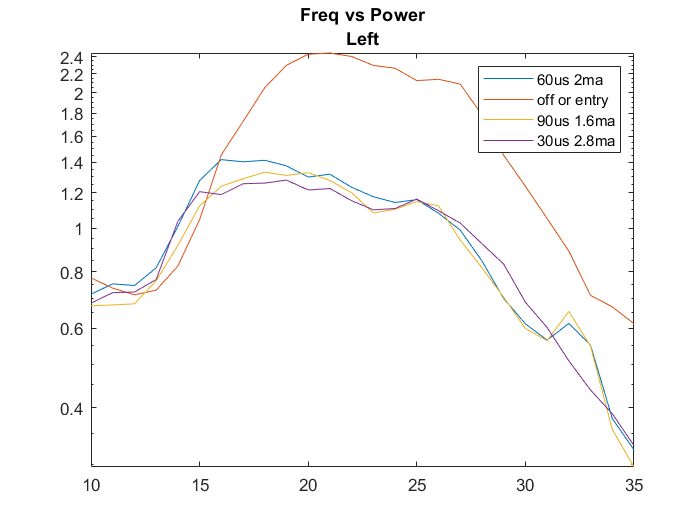

clear all;
%get the json 
cd('C:\Users\sydne\Documents\github\perceive\patientData')
jsonFiles = 'Report_Json_Session_Report_Patient2_final.json'; 
js = jsondecode(fileread(jsonFiles));
%set back to the correct directory 
cd('C:\Users\sydne\Documents\github\perceive\postAnalysis') 

%just hard coding that the first four in the brainsenselfp are for the left
%and the last four are for the right...I think! 

%% create a struct of the relevant data from brainsense 
leng = numel(js.BrainSenseLfp);
data = struct;
for i=1:4
    x = num2str(i);
    field = append("treatment", x);
    data.(field).channel = js.BrainSenseLfp(i).Channel;
    data.(field).time = datetime(replace({js.BrainSenseLfp(i).FirstPacketDateTime}, {'T', 'Z'},  {' ', ''}));
    data.(field).pw = js.BrainSenseLfp(i).TherapySnapshot.Left.PulseWidthInMicroSecond;
    data.(field).ma = js.BrainSenseLfp(i).TherapySnapshot.Left.LowerLimitInMilliAmps;
    data.(field).timeDomain = js.BrainSenseTimeDomain(i).TimeDomainData;
end
%% do pwelch on the LFP recording
%uncomment the subplot lines to just create a 5x1 subplot 
fs=250;
nfft=250;
window=250;
overlap=150;
%subplot(leng, 1, 1)
for i=1:4
    %make i usable for indexing into the struct 
    x = num2str(i);
    field = append("treatment", x);
    %calculate values
    t = data.(field).timeDomain;
    [pxx,f] = pwelch(t,window,overlap,nfft,fs);
    data.(field).LFPpower = pxx;
    data.(field).freq = f;
    fbeta = f > 12 & f < 33; 
    data.(field).avg = mean(pxx(fbeta));
    
    %subplot(leng, 1, i)
    semilogy(f,sqrt(pxx))
    xlim([10 35])
    hold on
end
title(["Freq vs Power", "Left"])

%get legend info 
%some parts must be hard coded bc 
for i = 1:4 
    x = num2str(i);
    field = append("treatment", x);
    pw = num2str(data.(field).pw); 
    ma = num2str(data.(field).ma);
    legendVal{i} = ((append(pw, "us ", ma, "ma")));
end 
legendVal{2} = "off or entry";
%legendVal{5} = "entry";
legend(legendVal{1}, legendVal{2}, legendVal{3}, legendVal{4});



for i = 1:4 
    x = num2str(i);
    field = append("treatment", x);
    means(i) = data.(field).avg;
end 

Tmean = array2table(means', 'VariableNames', {'Average Power in Beta Region (mV)'});
Tname = cell2table(legendVal', 'VariableNames', {'Treatment'}); 
tbl = [Tname Tmean];
sortrows(tbl, {'Average Power in Beta Region (mV)'}, 'descend')

ans = 4×2 table
      Treatment       Average Power in Beta Region (mV)
    ______________    _________________________________

    "off or entry"                 3.3567              
    "60us 2ma"                     1.2293              
    "90us 1.6ma"                   1.1154              
    "30us 2.8ma"                    1.115              


Right Side 

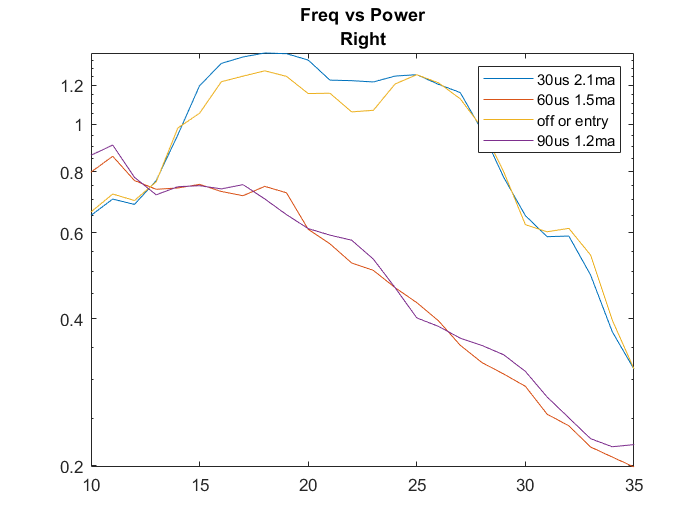

clear all;
%get the json 
cd('C:\Users\sydne\Documents\github\perceive\patientData')
jsonFiles = 'Report_Json_Session_Report_Patient2_final.json'; 
js = jsondecode(fileread(jsonFiles));
%set back to the correct directory 
cd('C:\Users\sydne\Documents\github\perceive\postAnalysis') 

%just hard coding that the first four in the brainsenselfp are for the left
%and the last four are for the right...I think! 
figure;
leng = numel(js.BrainSenseLfp);
data = struct;
for i=5:8
    x = num2str(i);
    field = append("treatment", x);
    data.(field).channel = js.BrainSenseLfp(i).Channel;
    data.(field).time = datetime(replace({js.BrainSenseLfp(i).FirstPacketDateTime}, {'T', 'Z'},  {' ', ''}));
    data.(field).pw = js.BrainSenseLfp(i).TherapySnapshot.Right.PulseWidthInMicroSecond;
    data.(field).ma = js.BrainSenseLfp(i).TherapySnapshot.Right.LowerLimitInMilliAmps;
    data.(field).timeDomain = js.BrainSenseTimeDomain(i).TimeDomainData;
end
%% do pwelch on the LFP recording
%uncomment the subplot lines to just create a 5x1 subplot 
fs=250;
nfft=250;
window=250;
overlap=150;
%subplot(leng, 1, 1)
for i=5:8
    %make i usable for indexing into the struct 
    x = num2str(i);
    field = append("treatment", x);
    %calculate values
    t = data.(field).timeDomain;
    [pxx,f] = pwelch(t,window,overlap,nfft,fs);
    data.(field).LFPpower = pxx;
    data.(field).freq = f;
    fbeta = f > 12 & f < 33; 
    data.(field).avg = mean(pxx(fbeta));
    
    %subplot(leng, 1, i)
    semilogy(f,sqrt(pxx))
    xlim([10 35])
    hold on
end
title(["Freq vs Power", "Right"])

%get legend info 
%some parts must be hard coded bc 
for i=1:4
    x = num2str(i+4);
    field = append("treatment", x);
    pw = num2str(data.(field).pw); 
    ma = num2str(data.(field).ma);
    legendVal{i} = ((append(pw, "us ", ma, "ma")));
end 
%need to investigate discrepency between json and pdf summary
legendVal{3} = "off or entry";
%legendVal{5} = "entry";
legend(legendVal{1}, legendVal{2}, legendVal{3}, legendVal{4});


for i=1:4
    x = num2str(i+4);
    field = append("treatment", x);
    means(i) = data.(field).avg;
end 

Tmean = array2table(means', 'VariableNames', {'Average Power in Beta Region (mV)'});
Tname = cell2table(legendVal', 'VariableNames', {'Treatment'}); 
tbl = [Tname Tmean];
sortrows(tbl, {'Average Power in Beta Region (mV)'}, 'descend')

ans = 4×2 table
      Treatment       Average Power in Beta Region (mV)
    ______________    _________________________________

    "30us 2.1ma"                    1.2729             
    "off or entry"                  1.1205             
    "90us 1.2ma"                   0.30678             
    "60us 1.5ma"                   0.30447             
